clear

a = arduino('COM10','Uno','Libraries','Servo');

s = servo(a, 'D3', 'MinPulseDuration', 700*10^-6, 'MaxPulseDuration', 2300*10^-6)

configurePin(a,'A3');

tic;
while toc < 6000
    voltage = readVoltage(a,'A3');
    %distance = read_sharp(voltage)
    pause(1);
end 

for ang = 1:increment:180
    
end 

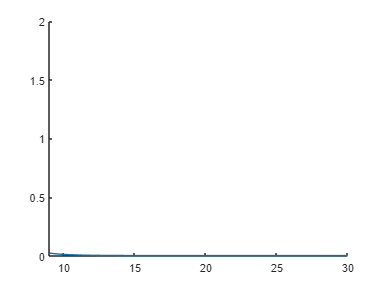

clf
position = 9.25:0.5:24;
%plot(position, filtered_vs,'.')
hold on
fplot(@(x) 18.9*exp(-0.7578*x))
xlim([9, 30]);
ylim([0,2])

filtered_vs = filter(a)

Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position
Move to new position


filtered_vs =     2.1212    2.0430    1.9648    1.8915    1.8328    1.7644    1.7155    1.6520    1.5982    1.5445    1.5054    1.4541    1.4174    1.3832    1.3465    1.3099    1.2903    1.2610    1.2195    1.1975    1.1437    1.0997    1.0802    1.0459    1.0068    0.9531    0.9531    0.8944    0.9140    0.9140


save("FilteredVoltages","filtered_voltages","position");

function filtered_voltages = filter(a)
    voltages = [];
    filter_voltages = [];
    for n = 1:30
        for v = 1:30
            voltages(v) = readVoltage(a,'A5');
        end 
        filtered_voltages(n) = median(voltages);
        voltages = [];
        disp("Move to new position");
        pause(10);
    end 
end